# Creating and Training a CNN to Classify Traffic Signs

For the Week 1 Project, you will:

- Prepare the traffic signs dataset for training

- Create a simple CNN

- Train the model to classify traffic signs

- Evaluate your trained model on test data

After you have finished, please proceed to the **"Project: Classifying Traffic Signs with a Simple CNN" **assessment to answer questions about your results.

## Prepare Your Data for Training

Inside the "Traffic Signs" folder, the data is already separated into Train and Test folders. 

Create an image datastore from the training dataset named `imdsSigns`:

% Select the location of the training data set:
filename = "F:\MY FOLDER\Study\Deep Learninig Computer Vision -Coursera\Data\Traffic Signs\Train";
imdsSigns = imageDatastore('F:\MY FOLDER\Study\Deep Learninig Computer Vision -Coursera\Data\Traffic Signs\Train', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

Use 80% of your data for training, leaving the remaining images for validation. Make sure to randomize which images are assigned to the validation set.

[imdsTrain, imdsValidation] = splitEachLabel(imdsSigns, 0.8, 'randomized');

## Preview the Training Data

Before you dive into building your network architecture, it's worth familiarizing yourself with the images in this data set. 

Run this section several times to preview some of the training data:

img = read(imdsSigns);
size(img)

ans =     41    39     3


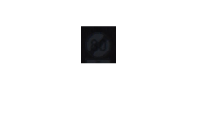

imshow(img)

countEachLabel(imdsValidation)

ans = 9×2 table
         Label         Count
    _______________    _____

    End Speed Limit     20  
    Speed Limit 100     20  
    Speed Limit 120     20  
    Speed Limit 20      20  
    Speed Limit 30      20  
    Speed Limit 50      20  
    Speed Limit 60      20  
    Speed Limit 70      20  
    Speed Limit 80      20  


Notice how many of the images are small, dark, blury, or otherwise difficult to see. 

All images are in RGB format, with sizes  $m \times n \times 3$, but they have a range of different sizes. Before you can train, you will have to resize these images to match the image input layer.

## Define the Network Architecture

The following code will open the Deep Network Designer App. Use the app to create and export a network with the following layers:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer`

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

- `classificationLayer`

Make sure you specify the correct `OutputSize` for `fullyConnectedLayer`.

if isMATLABReleaseOlderThan("R2024a")
    deepNetworkDesigner
else
    deepNetworkDesigner -v1
end

% Insert the code generated from the Deep Network Designer App:

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(9,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];


## Resize Your Training Data

Resize the training and validation data to match the `InputSize` that you set above:

AugTrain=augmentedImageDatastore([227,227],imdsTrain)

AugTrain =   augmentedImageDatastore with properties:

             NumObservations: 720
                       Files: {720×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


AugVal=augmentedImageDatastore([227,227],imdsValidation)

AugVal =   augmentedImageDatastore with properties:

             NumObservations: 180
                       Files: {180×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## Setting the Training Options

Finally, set your training options. You'll investigate training options in more detail later in this course. For now, use the same options as you saw in the video:

- Set the solver to `"adam"`

- Include the validation data you set aside earlier

- Set the Shuffle option to `"every-epoch"`

- Set the Plots option to `"training-progress"`

% Insert code to set the training options:
opts=trainingOptions("adam","ValidationData",AugVal,"Shuffle","every-epoch","Plots","training-progress")

opts =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 30
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validation

## Train the Network

It's finally time to train your network! 

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       15.62% |       13.89% |      45.6827 |    6541.6040 |          0.0010 |
|      10 |          50 |       00:04:37 |       75.78% |       48.33% |     162.6620 |     499.1754 |          0.0010 |
|      20 |         100 |       00:09:21 |       83.59% |       57.78% |      41.6281 |     222.1773 |          0.0010 |
|      30 |         150 |       00:14:28 |       98.44% |       58.33% |       1.1746 |   

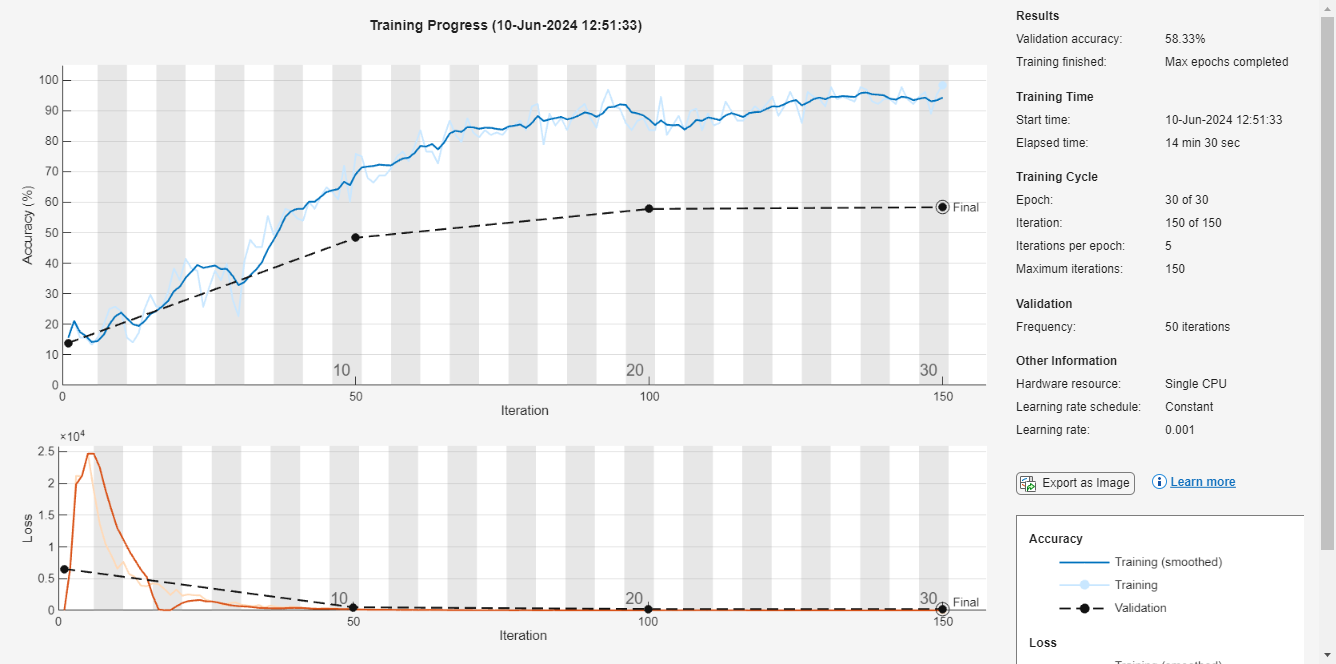

Net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% Insert code to train your network:
Net=trainNetwork(AugTrain,layers,opts)

Training will likely take about 20 minutes using a CPU.

## Performance on Test Data

Once you have trained your network, you should examine its performance on your test data.

Don't forget to resize your images to match the expected input size for your trained network:

filenameTest = "F:\MY FOLDER\Study\Deep Learninig Computer Vision -Coursera\Data\Traffic Signs\Test";
imdstest=imageDatastore("F:\MY FOLDER\Study\Deep Learninig Computer Vision -Coursera\Data\Traffic Signs\Test",IncludeSubfolders=true,LabelSource="foldernames")

imdstest =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011221.png';
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011223.png';
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011224.png'
                               ... and 285 more
                              }
                     Folders: {
                              ' ...\Deep Learninig Computer Vision -Coursera\Data\Traffic Signs\Test'
                              }
                      Labels: [End Speed Limit; End Speed Limit; End Speed Limit ... and 285 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
          

augTest=augmentedImageDatastore([227,227],imdstest)

augTest =   augmentedImageDatastore with properties:

             NumObservations: 288
                       Files: {288×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


Finally, use your test data to evaluate your trained network, including calculating the test accuracy and creating a confusion chart. You may need to click the arrow and open your confusion charts in the figure window to see them well:

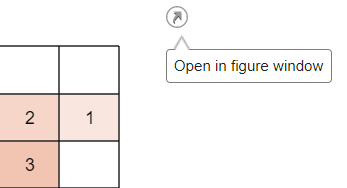

% Classify your test data:
testpreds = classify(Net,augTest)

testpreds = 288×1 categorical array
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     Speed Limit 70 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 


% Compute the test accuracy and create a confusion chart:
testaccuracy = nnz(testpreds==imdstest.Labels)/length(testpreds)

testaccuracy = 0.6528

YTest = imdstest.Labels;
% Generate the confusion matrix
confMat = confusionmat(YTest, testpreds);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

    31     0     0     0     0     0     0     1     0
     0    20     6     1     2     0     0     3     0
     0     3    20     0     1     3     0     4     1
     0     1     0    29     1     0     0     1     0
     0     0     0     5    21     2     4     0     0
     2     2     0     1     5    17     4     1     0
     0     2     2     0     1     1    22     3     1
     0     2     2     0     3     0     1    22     2
     0     9     4     0     4     2     5     2     6



% Calculate the number of misclassifications for each class
numMisclassified = sum(confMat, 2) - diag(confMat);

% Find the class with the maximum number of misclassifications
[~, mostMisclassifiedClassIdx] = max(numMisclassified);

% Get the class labels
classLabels = categories(YTest);

% Find the label of the most misclassified class
mostMisclassifiedClass = classLabels(mostMisclassifiedClassIdx);

disp(['Most misclassified class: ', char(mostMisclassifiedClass)]);

Most misclassified class: Speed Limit 80


disp(['Number of misclassifications: ', num2str(numMisclassified(mostMisclassifiedClassIdx))]);

Number of misclassifications: 26


While not perfect, this network performs surprisingly well considering the limited data set and the relatively simple architecture of your neural network. Later in this course, you will see how to achieve much better accuracy and loss values for this dataset.

Once you have completed this reading, proceed to the "Week 1 Project: Classifying Traffic Signs with a Simple CNN" quiz. You may want to keep this completed live script open as a reference as you answer questions about your results.

*Copyright 2024 The MathWorks, Inc.*